# Comprobar Imagenes

Kmeans

load modelos.mat

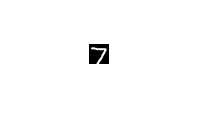

yfit = categorical
     7 


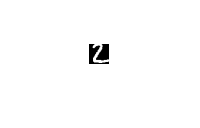

yfit = categorical
     2 


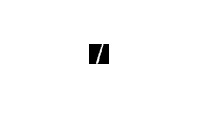

yfit = categorical
     1 


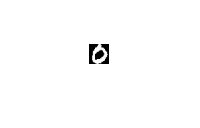

yfit = categorical
     0 


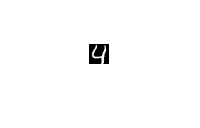

yfit = categorical
     4 


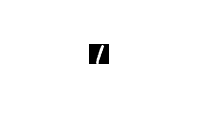

yfit = categorical
     1 


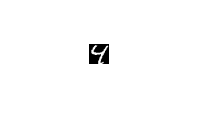

yfit = categorical
     9 


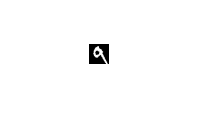

yfit = categorical
     9 


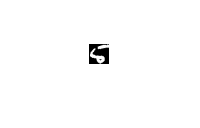

yfit = categorical
     5 


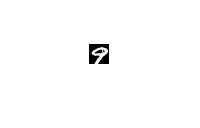

yfit = categorical
     9 


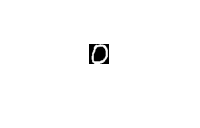

yfit = categorical
     0 


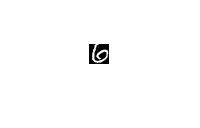

yfit = categorical
     6 


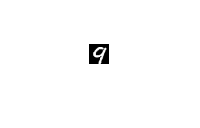

yfit = categorical
     9 


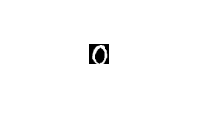

yfit = categorical
     0 


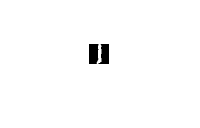

yfit = categorical
     1 


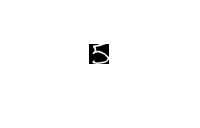

yfit = categorical
     5 


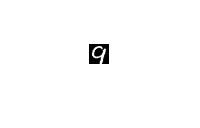

yfit = categorical
     9 


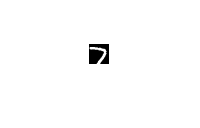

yfit = categorical
     7 


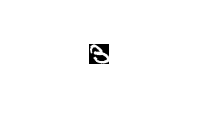

yfit = categorical
     5 


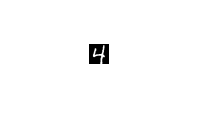

yfit = categorical
     4 


x = 20;
totalIm = ones(1,x);
for k = 1:x
    if k < 10
        im = imread(strcat( '.\per_provar-20200611\num1' ,'0', int2str(k) ,'.png'));
    else
        im = imread(strcat('.\per_provar-20200611\num1' ,int2str(k) ,'.png'));
    end
    im = mat2gray(im);
    [testfeatures1] = extractfeatureswithWaveletScattering([im]);
    [testfeatures2] = extractfeatureswithKMeans([im]);
    testfeatures = [testfeatures1 testfeatures2];
    
    yfit = predict(maxModel,testfeatures);
    figure;
    imshow(im)
    yfit
end


%totalIm


%study_of_model(maxModel,testfeatures,testlabels)



Neural Network

labelsPredict = categorical
     7 


labelsPredict = categorical
     2 


labelsPredict = categorical
     1 


labelsPredict = categorical
     0 


labelsPredict = categorical
     4 


labelsPredict = categorical
     1 


labelsPredict = categorical
     4 


labelsPredict = categorical
     9 


labelsPredict = categorical
     5 


labelsPredict = categorical
     9 


labelsPredict = categorical
     0 


labelsPredict = categorical
     6 


labelsPredict = categorical
     9 


labelsPredict = categorical
     0 


labelsPredict = categorical
     1 


labelsPredict = categorical
     5 


labelsPredict = categorical
     9 


labelsPredict = categorical
     7 


labelsPredict = categorical
     3 


labelsPredict = categorical
     4 


x = 20;
for k = 1:x
    if k < 10
        im = imread(strcat( '.\per_provar-20200611\num1' ,'0', int2str(k) ,'.png'));
    else
        im = imread(strcat('.\per_provar-20200611\num1' ,int2str(k) ,'.png'));
    end
    im = mat2gray(im);
    figure;
    imshow(im)
    labelsPredict = classify(net2,im)
end

Funciones

function [features] = extractfeatureswithWaveletScattering(images)
    sf = waveletScattering2('ImageSize', [28 28]);
    [~, ~, nimages] = size(images);
    for i = 1:nimages
        im = imresize(images(:,:,i),[28 28]);
        if (i == 1)
           feature  = helperScatImages(sf,im);
           l = length(feature);
           features = zeros(nimages, l);
           features(1,:) = feature';
        else
            features(i,:)  = helperScatImages(sf,im)';
        end
    end
end
function features = helperScatImages(sf,x)
% This function is only to support examples in the Wavelet Toolbox.
% It may change or be removed in a future release.
% Copyright 2018 MathWorks
    smat = featureMatrix(sf,x,'transform','log');
    features = mean(mean(smat,2),3);
end

function [features] = extractfeatureswithKMeans(images)
    NClusters = 8;
    [MAXFILA, MAXCOL, nimages] = size(images);
    features = zeros(nimages, NClusters*2);
    [A,B] = meshgrid((1:20),(1:20));
    c=cat(2,A',B');
    d=reshape(c,[],2);
    for i = 1:nimages
        im = images(:,:,i);
        im = imbinarize(im);
        %im = ~im;
        %im
        %figure,imshow(im)
        %label = double(reshape(im,MAXFILA*MAXCOL,1));
        label = reshape(im,MAXFILA*MAXCOL,1);
        
        d1 = d(:,1);
        d2 = d(:,2);
        d1 = d1(label == 1);
        d2 = d2(label == 1);
        aux = [d1 d2];
        [~, clusterC] = kmeans(aux,NClusters);
        %[cluster_idx, clusterC] = kmeans(aux,NClusters);
        %label(label == 1) = cluster_idx;
        %eti=reshape(label,MAXFILA,MAXCOL);
        %figure,imshow(eti,[]),colormap(colorcube), title('imatge etiquetada')
        centreAux = sortrows(clusterC,1);
        %feature = zeros(1,length(centreAux));
        %for cont = 1:centreAux
        %    feature(cont) = norm(centreAux(cont,:));
        %end
        %features(i,:) = sort(feature);
        features(i,:) = reshape(centreAux,[],1);
    end
end